# ME441-001 Final Project

## Daniel Waggner + Corbin Strycker

Problem DFN:

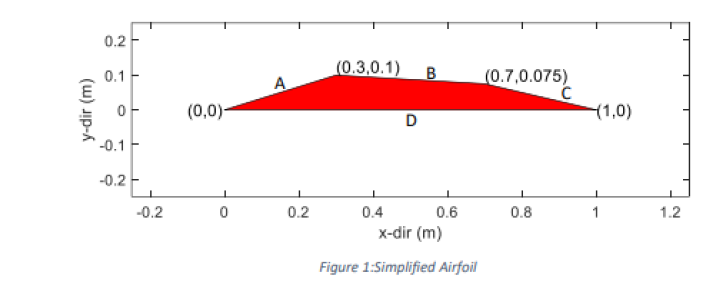

Initial CMDs

clear; 
clc;
close all;
format short;

Data

% Angle of Attack
alpha = 10;
% Requested Mach Number(s)
M1Init = 3.0; 

Variable DFNs

% Flow Vector
flowVectorMag = 0.35;
flowVectorPosx = -1 * flowVectorMag * cosd(alpha);
flowVectorPosy = flowVectorMag * sind(alpha); 

xvalstop = [flowVectorPosx, 0, 0.3, 0.7, 1.0];
yvalstop = [flowVectorPosy, 0, 0.1, 0.075, 0];

xvalsbottom = [flowVectorPosx, 0, 1.0];
yvalsbottom = [flowVectorPosy, 0, 0];

Assumptions:

    1. Acting Fluid is Air modeled as a callorically perfect gas

    2. Frictionless Flow (Inviscid)

    3. Fluid is Air @ STP

gamma = 1.4;
R = 287; % J/kg-K
T_flow_abs = 20+273; % k
P_flow = 101325; % Pa
rho_flow = 1.21; % kg/m^3

Plots


% alpha = 10;
% figure(1);
% hold on;
% [Flift, Fdrag] = ...
%     airfoilPropertiesPlotter(P_flow,T_flow_abs,...
%     M1Init, xvalstop, yvalstop, xvalsbottom, yvalsbottom, alpha,...
%     rho_flow, gamma, flowVectorPosx, flowVectorPosy, R);
% fprintf("Lift and Drag  %4.2f kN/m and %4.2f kN/m", ...
%         Flift, Fdrag);
% hold off;
% pause(10);
% 
% alpha = 10;
% figure(2);
% hold on;
% [Flift, Fdrag] = ...
%     airfoilPropertiesPlotter(P_flow,T_flow_abs,...
%     M1Init, xvalstop, yvalstop, xvalsbottom, yvalsbottom, alpha,...
%     rho_flow, gamma, flowVectorPosx, flowVectorPosy, R);
% fprintf("Lift and Drag  %4.2f kN/m and %4.2f kN/m", ...
%         Flift, Fdrag);
% hold off;
% pause(10);


%Creating Alpha Variation Animation
alpha = -10:1:10; 
k = 1;

workingDir = pwd;
mkdir(workingDir,'images');

while k <= length(alpha)
    fig = figure("Resize","off");
    fprintf(join(["Generating frame ", num2str(floor(k)),...
        " of ", num2str(floor(length(alpha))), "\n"]));
    hold on;
    flowVectorMag = 0.35;
    flowVectorPosx = -1 * flowVectorMag * cosd(alpha(k));
    flowVectorPosy = flowVectorMag * sind(alpha(k));
    xvalstop = [flowVectorPosx, 0, 0.3, 0.7, 1.0];
    yvalstop = [flowVectorPosy, 0, 0.1, 0.075, 0];

    xvalsbottom = [flowVectorPosx, 0, 1.0];
    yvalsbottom = [flowVectorPosy, 0, 0];
    [Flift, Fdrag] = ...
        airfoilPropertiesPlotter(P_flow,T_flow_abs,...
        M1Init, xvalstop, yvalstop, xvalsbottom,...
        yvalsbottom, alpha(k),rho_flow, gamma,...
        flowVectorPosx, flowVectorPosy, R);
        FL(k) = Flift;
        FD(k) = Fdrag;
        fprintf("Saving Frame...\n");
        pause(1);
        saveName = join(["Animation Frame ",...
            num2str(floor(k)),".jpg"]);
        fullfile(workingDir, 'images', saveName);
        exportgraphics(fig,saveName,'Resolution',1080);
        hold off;
        k = k + 1;
end

fprintf("Generating Animation...\n");

imageNames = dir(fullfile(workingDir,'images','*.jpg'));
imageNames = {imageNames.name}';

videoFileName = 'Airfoil_Animation.avi';
outputVideo = VideoWriter(fullfile( ...
    workingDir,videoFileName));
open(outputVideo);

for ii = 1:length(imageNames)
    fprintf(join(["Reading ", num2str(floor(ii)), ...
        " of ", num2str(floor(length(imageNames))),...
        " frames...\n"]));
   img = imread(fullfile(workingDir,'images',imageNames{ii}));
   writeVideo(outputVideo,img)
   pause(0.5);
end

close(outputVideo);

airfoilAnimation = VideoReader(fullfile(...
    workingDir,videoFileName));
ii = 1;

while hasFrame(airfoilAnimation)
   mov(ii) = im2frame(readFrame(airfoilAnimation));
   ii = ii+1;
end

figure 
imshow(mov(1).cdata, 'Border', 'tight');

movie(mov,1)

%Uncomment the code or copy it into the console
%   to view the animation (my PC cannot deal with
%   trying to run the script and then playing the
%   animation

%       movie(frame, 20)

%   salesartillery.com/fs/top-100-aerospace-companies
%   usajobs